# **Example of Streamer data processing**

## Introduction

**Authors**: I. Abakumov, 

**Publication date**: 22nd of October 2019

**E-mail**: ivan.abakumov@fu-berlin.de

## Upload MLIB library

clear; close all; clc;
mlibfolder = '/data/ivan/share/MLIB/';
path(path, mlibfolder);
add_mlib_path;
%https://github.com/Abakumov/MLIB


## Set size of the grid

G=GridClass;

% [m]        [m]          [m]          [s]
G.x0=0;     G.y0=0;   G.z0=0;         G.t0 = 0.0;           % initial point
G.nx=1840;  G.ny=1;   G.nz=300;       G.nt = 8001;          % grid size
G.dx=100;   G.dy=1;   G.dz=100;       G.dt = 0.002;         % grid step (meter)

G.gridInfo;

Information about grid:
x0=0, dx=100, Nx=1840.
y0=0, dy=1, Ny=1.
z0=0, dz=100, Nz=300.
t0=0, dt=0.002, Nt=8001.


G.setGrid;
Gold = oldGrid(G);

## Apply fk filtering in SU

required = 0; 
if(required)
    for i = 1001:2401
        sufilein = ['/remote/data/ivan/Streamer/data/MC15_' num2str(i) '.su'];
        sufileout = ['/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_' num2str(i) '.su'];
        if exist('sufilein','file') == 0 
            setenv('SUFNAMEIN', sufilein); 
            setenv('SUFNAMEOUT', sufileout); 
            %!echo $SUFNAMEIN
            %!echo $SUFNAMEOUT
            !sudipfilt < $SUFNAMEIN amps=0,0,1,1,0,0 slopes=-0.002,-0.001,-0.0008,0.0008,0.001,0.002 dx=12.5 > $SUFNAMEOUT
        else 
            disp(['Worning: no file'])
            disp('sufilein')
        end
    end

sudipfilt < $SUFNAMEIN amps=0,0,1,1,0,0 slopes=-0.002,-0.001,-0.0008,0.0008,0.001,0.002 dx=12.5 > $SUFNAMEOUT: Interrupt

sudipfilt: fgettr.c: bad first header


end

## Load SU data

data  = read_su_file('/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_2401.su');

/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_2401.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_2401.sgy


traces = data.traces; 
headers = get_segy_headers(data);

## Example of raw data

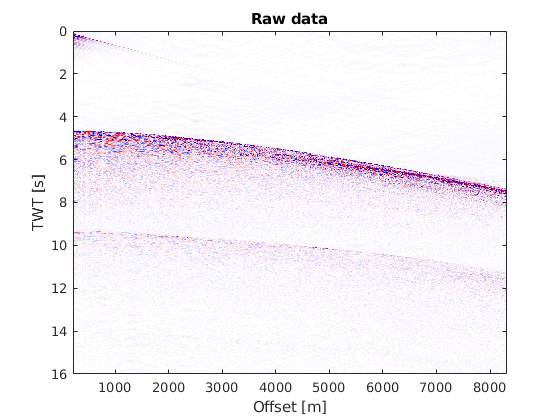

figure(1)
imagesc(headers.offset,G.tt,traces)
%pcolor(headers.offset,G.tt,traces)
%shading interp; 
%set(gca, 'YDir','reverse')
caxis([-10 10])
colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));
xlabel('Offset [m]')
ylabel('TWT [s]')
title('Raw data')

## Data preprocessing

required = 0; 
if(required)
    STALTAtraces = zeros(size(traces));
    
    tic
    for i=1:648
    
        trace = traces(:,i);
        
        Nl = 125;               % sum range for LTA  500 ms 
        Ns = 35;                % sum range for STA  60 ms
        STA = movmean(trace.^2,[0, Ns-1]);
        LTA = movmean(trace.^2,[Nl-1, 0]);
        STALTA = STA./LTA;
        STALTA(1:Ns) = 0;
        STALTAtraces(:,i) = STALTA;
    end
    toc
end

## Plot STALTA traces

required = 0; 
if(required)
    figure(2)
    %S = SME(STALTAtraces,20);
    imagesc(headers.offset,G.tt,STALTAtraces)
    %pcolor(headers.offset,G.tt,traces)
    %shading interp; 
    %set(gca, 'YDir','reverse')
    caxis([0 20])
    colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));
    xlabel('Offset [m]')
    ylabel('TWT [s]')
    title('Raw data')
end

## Load Velocity model

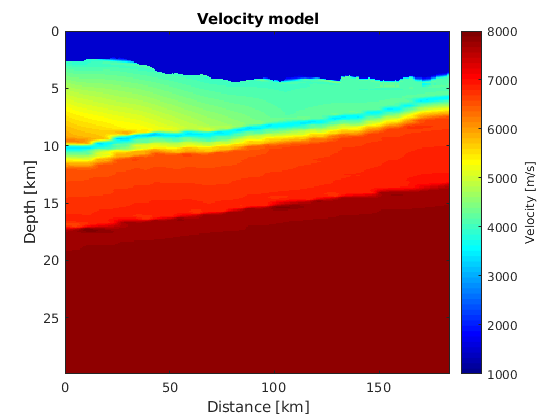

velmod  = read_segy_file('/home/ivan/Desktop/MLIB/Examples/Streamer_data_processing/Velocity_model.sgy');
velmod = velmod.traces'; 

figure(3)
imagesc(G.xx/1000,G.zz/1000,velmod')
%pcolor(headers.offset,G.tt,traces)
%shading interp; 
%set(gca, 'YDir','reverse')
xlabel('Distance [km]')
ylabel('Depth [km]')
title('Velocity model')
c = colorbar;
c.Label.String = 'Velocity [m/s]';
caxis([1000 8000]); 
colormap('jet')
%axis('equal')
axis([G.x0/1000 G.mx/1000 G.z0/1000 G.mz/1000])

%% Part II. Generate Migration 

TTI = zeros(G.nx,G.nz,G.nx);
tic
for i = 1:G.nx
    S = [G.xx(i), 0, 0];
    TTI(:,:,i) = FSM2D(Gold,S,velmod);
end
toc

Elapsed time is 149.351583 seconds.


tic
I = zeros(G.nx,G.nz);
filter = ones(G.nt, 1);
filter(1:2000) = 0;
filter(2000:2100) = (sin(linspace(0,pi/2,101))).^2;
filter(7901:8001) = (sin(linspace(-pi/2,0,101))).^2;  

for i = 1501:2:2001
    sufileout = ['/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_' num2str(i) '.su'];
    if exist(sufileout,'file') == 2 
        data  = read_su_file(sufileout);
        traces = data.traces; 
        headers = get_segy_headers(data);
        scalco = 100;                        
        headers.sx = headers.sx/scalco; 
        headers.rx = headers.rx/scalco; 
        headers.cdpx = (headers.sx+headers.rx)/2;
        acq.sx = headers.sx; 
        acq.sz = 12*ones(size(headers.sx)); 
        acq.rx = headers.rx; 
        acq.rz = 9*ones(size(headers.sx));
        acq.gsx = x2grid(acq.sx,G.x0,G.dx,G.nx);
        acq.grx = x2grid(acq.rx,G.x0,G.dx,G.nx);
        acq.gsz = x2grid(acq.sz,G.z0,G.dz,G.nz);
        acq.grz = x2grid(acq.rz,G.z0,G.dz,G.nz);
        
        sind = acq.gsx(j);
        stti = TTI(:,:,sind);
        
        for j = 1:size(traces,2)
            u = traces(:,j);
            u = u.*filter; 
    
            rind = acq.grx(j);
            rtti = TTI(:,:,rind);
            tti = stti + rtti;
            amp = 1./(tti+G.dt).^2;
            
            tti = x2grid(tti,G.t0,G.dt,G.nt);
            I = I + amp.*u(tti); 
        end
        disp(num2str(i))
    else
        disp('Worning: no file')
        disp('sufileout')
    end
end

1501


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1503.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1503.sgy


1503


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1505.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1505.sgy


1505


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1507.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1507.sgy


1507


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1509.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1509.sgy


1509


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1511.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1511.sgy


1511


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1513.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1513.sgy


1513


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1515.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1515.sgy


1515


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1517.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1517.sgy


1517


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1519.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1519.sgy


1519


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1521.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1521.sgy


1521


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1523.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1523.sgy


1523


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1525.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1525.sgy


1525


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1527.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1527.sgy


1527


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1529.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1529.sgy


1529


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1531.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1531.sgy


1531


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1533.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1533.sgy


1533


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1535.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1535.sgy


1535


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1537.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1537.sgy


1537


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1539.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1539.sgy


1539


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1541.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1541.sgy


1541


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1543.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1543.sgy


1543


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1545.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1545.sgy


1545


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1547.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1547.sgy


1547


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1549.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1549.sgy


1549


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1551.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1551.sgy


1551


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1553.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1553.sgy


1553


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1555.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1555.sgy


1555


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1557.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1557.sgy


1557


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1559.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1559.sgy


1559


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1561.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1561.sgy


1561


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1563.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1563.sgy


1563


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1565.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1565.sgy


1565


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1567.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1567.sgy


1567


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1569.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1569.sgy


1569


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1571.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1571.sgy


1571


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1573.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1573.sgy


1573


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1575.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1575.sgy


1575


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1577.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1577.sgy


1577


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1579.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1579.sgy


1579


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1581.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1581.sgy


1581


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1583.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1583.sgy


1583


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1585.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1585.sgy


1585


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1587.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1587.sgy


1587


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1589.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1589.sgy


1589


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1591.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1591.sgy


1591


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1593.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1593.sgy


1593


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1595.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1595.sgy


1595


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1597.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1597.sgy


1597


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1599.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1599.sgy


1599
1601


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1603.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1603.sgy


1603


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1605.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1605.sgy


1605


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1607.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1607.sgy


1607


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1609.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1609.sgy


1609


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1611.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1611.sgy


1611


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1613.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1613.sgy


1613


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1615.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1615.sgy


1615


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1617.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1617.sgy


1617


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1619.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1619.sgy


1619


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1621.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1621.sgy


1621


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1623.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1623.sgy


1623


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1625.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1625.sgy


1625


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1627.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1627.sgy


1627


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1629.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1629.sgy


1629


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1631.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1631.sgy


1631


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1633.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1633.sgy


1633


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1635.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1635.sgy


1635


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1637.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1637.sgy


1637


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1639.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1639.sgy


1639


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1641.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1641.sgy


1641


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1643.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1643.sgy


1643


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1645.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1645.sgy


1645


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1647.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1647.sgy


1647


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1649.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1649.sgy


1649


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1651.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1651.sgy


1651


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1653.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1653.sgy


1653


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1655.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1655.sgy


1655


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1657.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1657.sgy


1657


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1659.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1659.sgy


1659


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1661.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1661.sgy


1661


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1663.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1663.sgy


1663


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1665.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1665.sgy


1665


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1667.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1667.sgy


1667


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1669.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1669.sgy


1669


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1671.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1671.sgy


1671


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1673.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1673.sgy


1673


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1675.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1675.sgy


1675


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1677.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1677.sgy


1677


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1679.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1679.sgy


1679


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1681.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1681.sgy


1681


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1683.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1683.sgy


1683


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1685.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1685.sgy


1685


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1687.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1687.sgy


1687


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1689.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1689.sgy


1689


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1691.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1691.sgy


1691


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1693.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1693.sgy


1693


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1695.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1695.sgy


1695


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1697.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1697.sgy


1697


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1699.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1699.sgy


1699
1701


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1703.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1703.sgy


1703


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1705.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1705.sgy


1705


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1707.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1707.sgy


1707


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1709.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1709.sgy


1709


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1711.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1711.sgy


1711


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1713.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1713.sgy


1713


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1715.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1715.sgy


1715


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1717.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1717.sgy


1717


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1719.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1719.sgy


1719


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1721.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1721.sgy


1721


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1723.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1723.sgy


1723


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1725.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1725.sgy


1725


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1727.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1727.sgy


1727


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1729.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1729.sgy


1729


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1731.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1731.sgy


1731


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1733.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1733.sgy


1733


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1735.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1735.sgy


1735


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1737.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1737.sgy


1737


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1739.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1739.sgy


1739


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1741.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1741.sgy


1741


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1743.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1743.sgy


1743


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1745.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1745.sgy


1745


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1747.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1747.sgy


1747


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1749.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1749.sgy


1749


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1751.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1751.sgy


1751


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1753.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1753.sgy


1753


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1755.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1755.sgy


1755


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1757.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1757.sgy


1757


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1759.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1759.sgy


1759


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1761.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1761.sgy


1761


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1763.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1763.sgy


1763


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1765.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1765.sgy


1765


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1767.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1767.sgy


1767


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1769.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1769.sgy


1769


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1771.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1771.sgy


1771


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1773.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1773.sgy


1773


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1775.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1775.sgy


1775


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1777.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1777.sgy


1777


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1779.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1779.sgy


1779


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1781.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1781.sgy


1781


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1783.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1783.sgy


1783


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1785.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1785.sgy


1785


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1787.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1787.sgy


1787


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1789.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1789.sgy


1789


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1791.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1791.sgy


1791


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1793.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1793.sgy


1793


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1795.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1795.sgy


1795


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1797.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1797.sgy


1797


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1799.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1799.sgy


1799
1801


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1803.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1803.sgy


1803


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1805.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1805.sgy


1805


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1807.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1807.sgy


1807


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1809.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1809.sgy


1809


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1811.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1811.sgy


1811


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1813.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1813.sgy


1813


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1815.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1815.sgy


1815


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1817.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1817.sgy


1817


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1819.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1819.sgy


1819


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1821.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1821.sgy


1821


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1823.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1823.sgy


1823


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1825.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1825.sgy


1825


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1827.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1827.sgy


1827


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1829.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1829.sgy


1829


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1831.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1831.sgy


1831


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1833.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1833.sgy


1833


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1835.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1835.sgy


1835


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1837.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1837.sgy


1837


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1839.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1839.sgy


1839


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1841.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1841.sgy


1841


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1843.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1843.sgy


1843


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1845.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1845.sgy


1845


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1847.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1847.sgy


1847


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1849.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1849.sgy


1849


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1851.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1851.sgy


1851


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1853.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1853.sgy


1853


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1855.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1855.sgy


1855


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1857.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1857.sgy


1857


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1859.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1859.sgy


1859


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1861.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1861.sgy


1861


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1863.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1863.sgy


1863


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1865.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1865.sgy


1865


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1867.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1867.sgy


1867


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1869.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1869.sgy


1869


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1871.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1871.sgy


1871


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1873.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1873.sgy


1873


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1875.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1875.sgy


1875


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1877.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1877.sgy


1877


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1879.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1879.sgy


1879


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1881.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1881.sgy


1881


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1883.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1883.sgy


1883


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1885.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1885.sgy


1885


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1887.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1887.sgy


1887


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1889.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1889.sgy


1889


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1891.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1891.sgy


1891


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1893.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1893.sgy


1893


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1895.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1895.sgy


1895


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1897.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1897.sgy


1897


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1899.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1899.sgy


1899
1901


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1903.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1903.sgy


1903


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1905.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1905.sgy


1905


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1907.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1907.sgy


1907


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1909.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1909.sgy


1909


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1911.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1911.sgy


1911


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1913.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1913.sgy


1913


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1915.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1915.sgy


1915


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1917.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1917.sgy


1917


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1919.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1919.sgy


1919


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1921.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1921.sgy


1921


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1923.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1923.sgy


1923


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1925.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1925.sgy


1925


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1927.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1927.sgy


1927


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1929.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1929.sgy


1929


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1931.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1931.sgy


1931


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1933.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1933.sgy


1933


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1935.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1935.sgy


1935


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1937.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1937.sgy


1937


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1939.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1939.sgy


1939


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1941.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1941.sgy


1941


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1943.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1943.sgy


1943


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1945.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1945.sgy


1945


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1947.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1947.sgy


1947


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1949.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1949.sgy


1949


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1951.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1951.sgy


1951


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1953.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1953.sgy


1953


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1955.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1955.sgy


1955


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1957.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1957.sgy


1957


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1959.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1959.sgy


1959


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1961.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1961.sgy


1961


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1963.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1963.sgy


1963


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1965.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1965.sgy


1965


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1967.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1967.sgy


1967


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1969.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1969.sgy


1969


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1971.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1971.sgy


1971


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1973.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1973.sgy


1973


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1975.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1975.sgy


1975


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1977.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1977.sgy


1977


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1979.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1979.sgy


1979


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1981.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1981.sgy


1981


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1983.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1983.sgy


1983


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1985.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1985.sgy


1985


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1987.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1987.sgy


1987


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1989.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1989.sgy


1989


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1991.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1991.sgy


1991


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1993.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1993.sgy


1993


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1995.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1995.sgy


1995


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1997.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1997.sgy


1997


/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1999.su
/remote/data/ivan/Streamer/data_fk/MC15_dipfilt_1999.sgy


1999
2001


toc

Elapsed time is 1225.770284 seconds.




%  tind = floor(tti/G.dt) + 1;
%  dtti = tti/G.dt - floor(tti/G.dt);
%  image = image + amp.*((1-dtti).*U(tind) + dtti.*U(tind+1));


